clear

startN = 2;
endN = 50;


startX = -1;
endX = 1;


deviations = zeros(1, endN - startN + 1);

fprintf("Узлы Чебышёва:")

Узлы Чебышёва:

for n = startN:endN
    
    X = chebyshevRoots(startX, endX, n);

    Y = sin(X);

    P = lagrange(X, Y);
    %P = newton(X, Y);
    %P = polyfit(X, Y, length(X) - 1);

    miniStepX = 0.001;
    miniX = startX:miniStepX:endX;
    
    F = sin(miniX);
    P = polyval(P, miniX);
    
    deviations(n-startN+1) = deviation(miniX, F, P);
    fprintf("n = %d, maxDeviation = %.10f\n", n, deviations(n-startN+1))
end

n = 2, maxDeviation = 0.0772543851
n = 3, maxDeviation = 0.0396274706
n = 4, maxDeviation = 0.0009930426
n = 5, maxDeviation = 0.0005043840
n = 6, maxDeviation = 0.0000059884
n = 7, maxDeviation = 0.0000030236
n = 8, maxDeviation = 0.0000000209
n = 9, maxDeviation = 0.0000000105
n = 10, maxDeviation = 0.0000000000
n = 11, maxDeviation = 0.0000000000
n = 12, maxDeviation = 0.0000000000
n = 13, maxDeviation = 0.0000000000
n = 14, maxDeviation = 0.0000000000
n = 15, maxDeviation = 0.0000000001
n = 16, maxDeviation = 0.0000000001
n = 17, maxDeviation = 0.0000000005
n = 18, maxDeviation = 0.0000000003
n = 19, maxDeviation = 0.0000000015
n = 20, maxDeviation = 0.0000000037
n = 21, maxDeviation = 0.0000000205
n = 22, maxDeviation = 0.0000000762
n = 23, maxDeviation = 0.0000003165
n = 24, maxDeviation = 0.0000008845
n = 25, maxDeviation = 0.0000061927
n = 26, maxDeviation = 0.0000092304
n = 27, maxDeviation = 0.0000343795
n = 28, maxDeviation = 0.0001981878
n = 29, maxDeviation = 0.0001611044


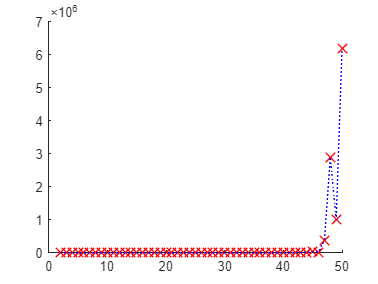



N = startN:endN;
hold on
plot(N, deviations, "rx", 'MarkerSize', 10, "LineWidth", 1)
plot(N, deviations, "b:", 'LineWidth', 1, "MarkerSize", 1)
hold off

fprintf("Равностоящие узлы:")

Равностоящие узлы:

for n = startN:endN
    
    X = linspace(startX, endX, n);
    %X = chebyshevRoots(startX, endX, n);

    Y = sin(X);

    P = lagrange(X, Y);
    %P = newton(X, Y);
    %P = polyfit(X, Y, length(X) - 1);

    miniStepX = 0.001;
    miniX = startX:miniStepX:endX;
    
    F = sin(miniX);
    P = polyval(P, miniX);
    
    deviations(n-startN+1) = deviation(miniX, F, P);
    fprintf("n = %d, maxDeviation = %.10f\n", n, deviations(n-startN+1))
end

n = 2, maxDeviation = 0.0599937474
n = 3, maxDeviation = 0.0599937474
n = 4, maxDeviation = 0.0012181651
n = 5, maxDeviation = 0.0009031414
n = 6, maxDeviation = 0.0000116308
n = 7, maxDeviation = 0.0000084150
n = 8, maxDeviation = 0.0000000701
n = 9, maxDeviation = 0.0000000505
n = 10, maxDeviation = 0.0000000003
n = 11, maxDeviation = 0.0000000002
n = 12, maxDeviation = 0.0000000000
n = 13, maxDeviation = 0.0000000000
n = 14, maxDeviation = 0.0000000001
n = 15, maxDeviation = 0.0000000003
n = 16, maxDeviation = 0.0000000002
n = 17, maxDeviation = 0.0000000040
n = 18, maxDeviation = 0.0000000062
n = 19, maxDeviation = 0.0000000233
n = 20, maxDeviation = 0.0000000077
n = 21, maxDeviation = 0.0000000500
n = 22, maxDeviation = 0.0000031921
n = 23, maxDeviation = 0.0000027713
n = 24, maxDeviation = 0.0000261583
n = 25, maxDeviation = 0.0000328611
n = 26, maxDeviation = 0.0000521297
n = 27, maxDeviation = 0.0039151795
n = 28, maxDeviation = 0.0086285162
n = 29, maxDeviation = 0.0236339158


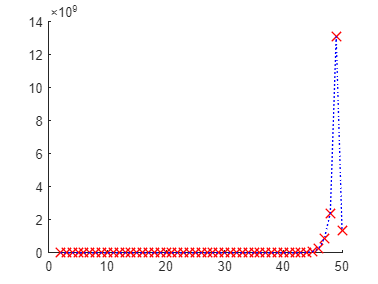



N = startN:endN;
figure
hold on
plot(N, deviations, "rx", 'MarkerSize', 10, "LineWidth", 1)
plot(N, deviations, "b:", 'LineWidth', 1, "MarkerSize", 1)
hold off